# Proximal Algorithm for Discrete Optimal Transport

The following code aims to solve


$$\min K(\gamma)$$


    subject to


$$\sum_{j} \gamma_{i,j} = m_i $$
    
$$\forall i \in [M],$$



$$\sum_{i} \gamma_{i,j} = n_j$$
    
$$\forall j \in [N],$$



$$\gamma_{i,j} \geq 0$$
    
$$\forall i\in [M], j\in [N].$$


Here $K$ is defined as $K(\gamma) = c:\gamma = \sum_{i,j} c_{i,j} \gamma_{i,j}$, with $c\geq 0$ a cost matrix.

## Preliminaries

To solve this problem, we will implement a Forward–Backward algorithm. In order to be able to state this algorithm, let us identify the simplex $C_1^m$ as the set


$$C_1^m := \left\{ x \in \mathbb{R}^{M\times N}: \, \sum_{j \in N} x_{i,j} = m_i \,\,\, \forall i \in [M] \wedge x\geq 0 \right\}$$


and similarly the simplex $C_2^n$ as the set


$$C_2^n := \left\{ x \in \mathbb{R}^{M\times N}: \, \sum_{i \in M} x_{i,j} = n_j \,\,\, \forall j \in [N] \wedge x\geq 0 \right\}.$$


We denote the intersection of these sets as $C = C_1^m \cap C_2^n$ and its indicator function as $\imath_C.$

Moreover, notice that $K$is a continuously differentiable function (as it is a lineal operator) and its derivative at any point in $\mathbb{R}^{M\times N}$ is the constant $\nabla K = c$. Matrix $c$ has a Lipschitz constant $\mu$ which coincides with its operator norm. Depending on the complexity (dimension) of the problem, we can use the spectral norm (largest singular value of $c$) or the simpler $\ell_1$ and $\ell_\infty$ induced norms.

## Algorithm statement

Now we present the Forward-backward algorithm which aims to minimise $K$satisfying the constraints imposed by sets $C_1^m$ and $C_2^n$:

- Let $\varepsilon \in (0,\mu^{-1}).$

- Let $x_0 \in \mathbb{R}^{M\times N}$.

- **For **$k \in \{1, 2, \ldots\}$`:`

-     Select $\gamma_k \in [\varepsilon, 2\mu^{-1} - \varepsilon]$.

-     Define $y_k := x_k - \gamma_k c$.

-     Select $\lambda_k \in [\varepsilon, 1]$.

-     Define $x_{k+1} := x_k + \lambda_k ( \mathrm{prox}_{\gamma_k \,\cdot \, \imath_C}(y_k) - x_k )$.

The proximal operator $\mathrm{prox}_{\gamma_k \,\cdot \, \imath_C}(y_k)$ present in step 7 will be computed using the next algorithm.

## Proximal operator

The proximal operator of the indicator function $\imath_C$ is computed taking the following steps:

- Let $\varepsilon \in (0,1).$

- Let $k = 0.$

- Select $v_{1,k} \in C_1^m$ and $v_{2,k} \in C_2^n.$

- **do while** $z\notin C$:

-     Define $z_k := y - \frac{1}{2}( v_{1,k} + v_{2,k} )$.

-     Select $\theta_k \in [\varepsilon, 2-\varepsilon]$.

-     
$$v_{1,k+1} := v_{1,k} + \theta_k \left( z_k  - \mathrm{proj}_{C_1^m} ( \theta_k^{-1} v_{1,k} + z_k ) \right)$$


-     
$$v_{2,k+1} := v_{2,k} + \theta_k \left( z_k  - \mathrm{proj}_{C_2^n} ( \theta_k^{-1} v_{2,k} + z_k ) \right)$$


-     
$$k = k+1.$$


- Return $z = \mathrm{prox}_{\imath_C}(y)$.

The projection operators $\mathrm{proj}_{C_1^m}$ and $\mathrm{proj}_{C_2^n}$ are computed using the function `project_simplex` from the Proximity Operator Repository. Likewise, the function `indicator_simplex` will be used in step 4 as an stopping criteria.

## General algorithm

If there is not much information for an initial point from $n$ and $m$, then we can further use an arbitrary initial point or use a point in $C$before we begin the iteration.

#### Numerical experimentation

The purpose of this section is to experimentate with larger instances. In all our calculations, we will sample points from$\mu = \mathcal{U}(0,1)$ and $\nu = \mathcal{U}(1,2)$. Moreover, we assume $M \neq N.$

- Linear distance

- Squared euclidean distance (parameter `'Squared Euclidean distance'`).

- Minkowski distance (parameter `'minkowski'`) with exponent `DistParameter`$=0.5$.

% Perfomance values
obj  = [];
temp = [];

for jj = 0:0
    M = 200 + jj*200;                   N = 100 + jj*100;
    m = (1/M) * ones(M,1);     n = (1/N) * ones(N,1);
    
    % Store basic vectors
    save('Instances/Vector_m_' + string(M) + '.mat', 'm')
    save('Instances/Vector_n_' + string(N) + '.mat', 'n')
    
    for ii = 1:2
        % Compute distances
        rng(2020)
        X = rand(M,1);
        Y = 1 + rand(N,1);
        if      ii == 1
            c = squareform(pdist([X;Y]));
            c = c(1:M, M+1:end);
            save('Instances/Cost_EU_' + string(M) + '_' + string(N) + '.mat', 'c')  % Store matrix for reproducibility
        elseif  ii == 2
            c = squareform(pdist([X;Y],'squaredeuclidean'));
            c = c(1:M, M+1:end);
            save('Instances/Cost_SE_' + string(M) + '_' + string(N) + '.mat', 'c')  % Store matrix for reproducibility
        else
            c = squareform(pdist([X;Y],'minkowski',0.5));
            c = c(1:M, M+1:end);
            save('Instances/Cost_MI_' + string(M) + '_' + string(N) + '.mat', 'c')  % Store matrix for reproducibility
        end
        clear X Y;
        
        %% 
        % Run algorithm
        %%
        [x,obj_e,temp_m] = Forward_Backward(c,m,n);
        temp(end+1) = temp_m;
        obj(end+1)  = obj_e;
    end
end

Store results

save('Instances/Results-Temp.mat', 'temp')
save('Instances/Results-Obj.mat', 'obj')

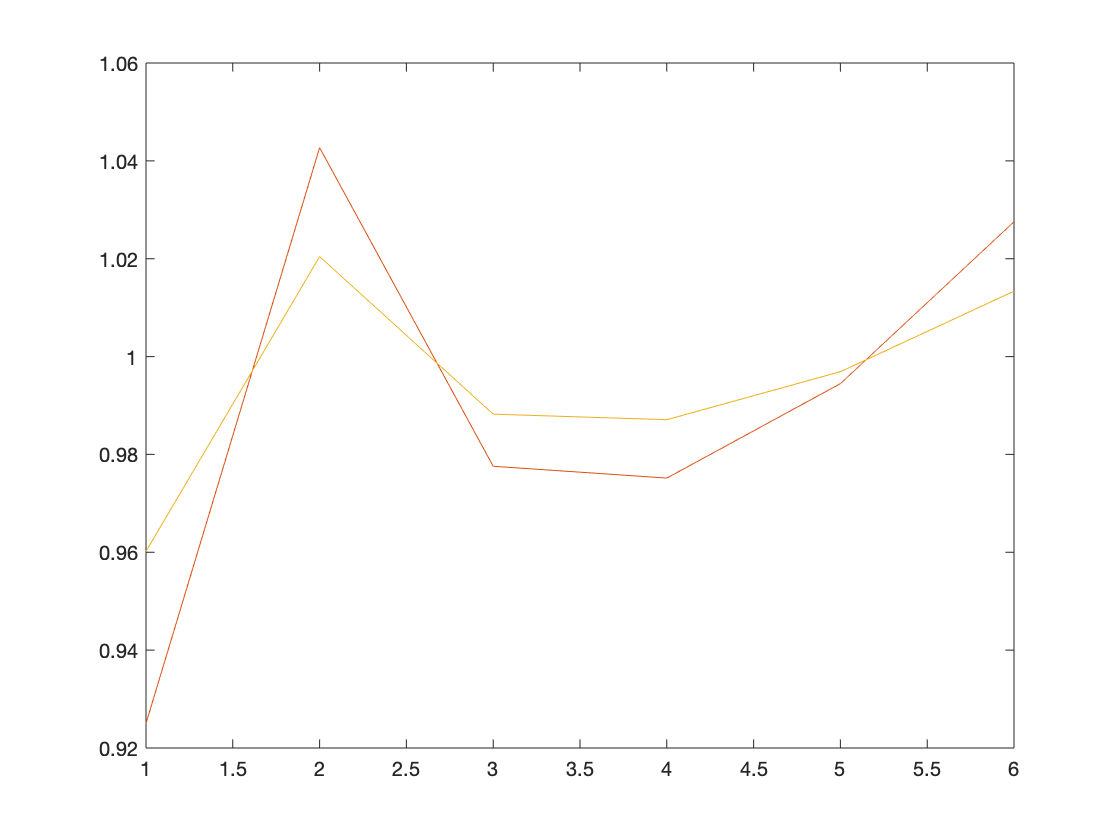

plot(obj(1:3:end))
hold on
plot(obj(2:3:end))
hold on
plot(obj(3:3:end))
hold off 

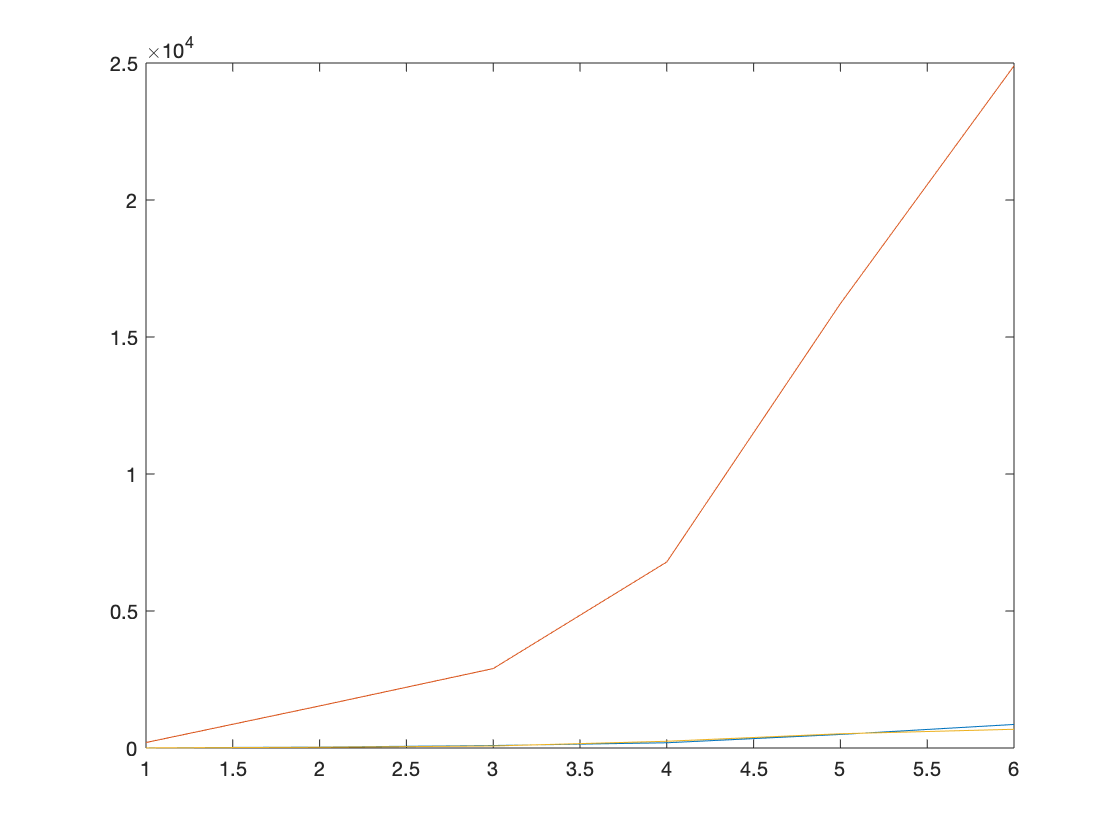

plot(temp(1:3:end))
hold on
plot(temp(2:3:end))
hold on
plot(temp(3:3:end))
hold off

# FISTA

## Algorithm statement

Now we present an adapted FISTA to minimise $K$satisfying the constraints imposed by sets $C_1^m$ and $C_2^n$:

- Let $\varepsilon \in (0,\mu^{-1}).$

- Let $x_0 \in \mathbb{R}^{M\times N}$, $z_0 = x_0$, $t_0 = 1$.

- Select $\mu > 0$.

- **For **$k \in \{1, 2, \ldots\}$`:`

-     Define $y_{k} := z_{k-1} - \mu^{-1} c$.

-     Define $x_{k} := \mathrm{prox}_{\mu^{-1} \,\cdot \, \imath_C}(y_{k}) =  \mathrm{prox}_{\imath_C}(y_{k})$.

-     Define $t_k := \frac{1 + \sqrt{1 + 4 t^2_{k-1}} }{2}$.

-     Define $\lambda_k := 1 + \frac{t_{k-1}-1}{t_k }$

-     Define $z_k := x_{k-1} + \lambda_k ( x_{k} - x_{k-1} )$.

% Perfomance values
obj  = [];
temp = [];

for jj = 0:0
    M = 200 + jj*200;                   N = 100 + jj*100;
    m = (1/M) * ones(M,1);     n = (1/N) * ones(N,1);
    
    % Store basic vectors
    save('Instances/Vector_m_' + string(M) + '.mat', 'm')
    save('Instances/Vector_n_' + string(N) + '.mat', 'n')
    
    for ii = 1:2
        % Compute distances
        rng(2020)
        X = rand(M,1);
        Y = 1 + rand(N,1);
        if      ii == 1
            c = squareform(pdist([X;Y]));
            c = c(1:M, M+1:end);
            save('Instances/Cost_EU_' + string(M) + '_' + string(N) + '.mat', 'c')  % Store matrix for reproducibility
        elseif  ii == 2
            c = squareform(pdist([X;Y],'squaredeuclidean'));
            c = c(1:M, M+1:end);
            save('Instances/Cost_SE_' + string(M) + '_' + string(N) + '.mat', 'c')  % Store matrix for reproducibility
        else
            c = squareform(pdist([X;Y],'minkowski',0.5));
            c = c(1:M, M+1:end);
            save('Instances/Cost_MI_' + string(M) + '_' + string(N) + '.mat', 'c')  % Store matrix for reproducibility
        end
        clear X Y;
        
        %% 
        % Run algorithm
        %%
        [x,obj_e,temp_m] = FISTA(c,m,n);
        temp(end+1) = temp_m;
        obj(end+1)  = obj_e;
    end
end

ans =    -9.2874    1.0000


ans =    -4.2590  100.0000


# Primal dual

# Linear programming

% Perfomance values
obj_lp  = [];
temp_lp = [];

for jj = 0:5
    M = 200 + jj*200;                   N = 100 + jj*100;
    m = (1/M) * ones(M,1);     n = (1/N) * ones(N,1);
    
    % Lin progr system Ax = b
    A = [kron( ones(1,N), speye(M) ); kron( speye(N), ones(1,M) )];
    b = [ m;n ];
    
    % Store basic vectors
    %save('Instances/Vector_m_' + string(M) + '.mat', 'm')
    %save('Instances/Vector_n_' + string(N) + '.mat', 'n')
    
    for ii = 1:2
        % Compute distances
        rng(2020)
        X = rand(M,1);
        Y = 1 + rand(N,1);
        if      ii == 1
            c = squareform(pdist([X;Y]));
            c = c(1:M, M+1:end);
            save('Instances/Cost_EU_' + string(M) + '_' + string(N) + '.mat', 'c')  % Store matrix for reproducibility
        elseif  ii == 2
            c = squareform(pdist([X;Y],'squaredeuclidean'));
            c = c(1:M, M+1:end);
            save('Instances/Cost_SE_' + string(M) + '_' + string(N) + '.mat', 'c')  % Store matrix for reproducibility
        else
            c = squareform(pdist([X;Y],'minkowski',0.5));
            c = c(1:M, M+1:end);
            save('Instances/Cost_MI_' + string(M) + '_' + string(N) + '.mat', 'c')  % Store matrix for reproducibility
        end
        clear X Y;
        
        
        options = optimoptions('linprog','Algorithm','dual-simplex','OptimalityTolerance', 1e-4, 'ConstraintTolerance',1e-6);
        tStart = tic;
        [x,fval,exitflag,output,lambda] = linprog(c(:),[],[],A,b, sparse(zeros(N*M,1)), [], options);
        temp_lp(end+1) = toc(tStart);
        obj_lp(end+1) = sum(fval);
    end
end

save('Instances/Results-Temp_LP.mat', 'temp_lp')
save('Instances/Results-Obj_LP.mat', 'obj_lp')

